**3 Comparison Bode Plots of Model Simulink Simulation DC-DC Buck Converter with Derived Type III Compensator Controller with Voltage Divider and Specific Op-Amp Implementations**

clc; 
clear all; 
close all;

%Identify Transfer Function Variable
s = tf('s');

% Assign Estimated Transfer Function From Model Simulink Simulation
REALBUCKTF = load("BuckModelTransferFunction.mat").ans

REALBUCKTF =
 
     2461 s^3 + 3.464e08 s^2 + 4.909e11 s + 1.083e16
  -----------------------------------------------------
  s^4 + 2642 s^3 + 6.172e07 s^2 + 8.008e10 s + 8.848e14
 
Continuous-time transfer function.
Model Properties



% Buck Converter Model Simulink Simulation Values for Reference
%Vin = 12;       % Input Voltage value (V)
%Vout = 5;       % Output Voltage value (V)
%R = 10;         % Load resistance (Ohm)
%L = 350e-6;     % Inductor value (H)
%C = 100e-6;     % Capacitor value (F)
%RL = 0.050;     % Inductor resistance (Ohm)
%RC = 0.025;     % Capacitor resistance (Ohm)
%D = 0.4569;     % Duty Cycle Constant
%PWM = 250e3;    % PWM Generator Switching Frequency (Hz)

% Buck Converter Values Relevant for Design
Vref= 1.2;       % Reference Voltage value (V)
Vout = 5;        % Output Voltage value (V)

% Type III Compensator Controller Values
OpAmp=tf(1e6,1);             % Perfect OpAmp Configuration
Rf1 = 20e3;                  % Resistor Rf1 value (Ohm)
Rc1 = 12.4e3;                % Resistor Rc2 value (Ohm)
Rf3 = 568;                   % Resistor Rf3 value (Ohm)
Cc2 = 200e-12;               % Capacitor Cc2 value (F)
Cc1 = 10.2e-9;               % Capacitor Cc1 value (F)
Cf3 = 3.7e-9;                % Capacitor Cf3 value (F) (Control this to make phase shift up and down)
Rf2=Rf1*Vref/(Vout-Vref);    % Voltage Divider Resistor Rf2 value (Ohm)

% Table of Type III Compensator Controller Values Displayed
compValues = [Rf1, Rf2, Rf3, Cc1, Cc2, Cf3, Rc1];
disp(table(Rf1, Rf2, Rf3, Cc1, Cc2, Cf3, Rc1))

     Rf1      Rf2      Rf3      Cc1        Cc2       Cf3       Rc1 
    _____    ______    ___    ________    _____    _______    _____

    20000    6315.8    568    1.02e-08    2e-10    3.7e-09    12400




% Derived Transfer Function for Type III Compensator Controller Accounting for Voltage Divider
COMP1 = ((Rc1+1/(s*Cc1))*(1/(s*Cc2)))/((Rc1+1/(s*Cc1))+(1/(s*Cc2)));
COMP2 = ((Rf3+1/(s*Cf3))*Rf1)/((Rf3+1/(s*Cf3))+Rf1);
COMP3 = (COMP1*Rf2/(COMP1+Rf2))/((COMP1*Rf2/(COMP1+Rf2))+COMP2); % Applying Voltage Divider
COMP4 = (COMP2*Rf2/(COMP2+Rf2))/((COMP2*Rf2/(COMP2+Rf2))+COMP1); % Applying Voltage Divider
COMPLETECOMP=(-1)*COMP3*feedback(OpAmp,COMP4)

COMPLETECOMP =
 
           -3.095e-186 s^29 - 3.978e-179 s^28 - 7.711e-173 s^27 - 5.143e-167 s^26 - 1.427e-161 s^25 - 1.641e-156 s^24 - 9.171e-152 s^23 - 2.741e-147 s^22 - 4.705e-143 s^21 - 4.775e-139 s^20 - 2.818e-135 s^19 - 8.9e-132 s^18 - 1.159e-128 s^17
  --------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  3.419e-193 s^30 + 4.691e-186 s^29 + 1.238e-179 s^28 + 1.383e-173 s^27 + 7.989e-168 s^26 + 2.521e-162 s^25 + 4.254e-157 s^24 + 3.553e-152 s^23 + 1.464e-147 s^22 + 2.94e-143 s^21 + 2.931e-139 s^20 + 1.374e-135 s^19 + 2.411e-132 s^18 + 4.829e-134 s^17
 
Continuous-time transfer function.


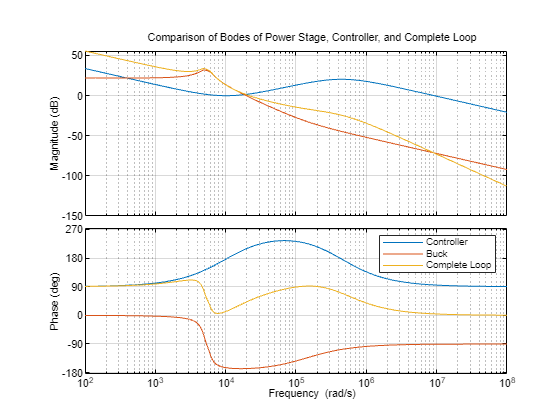


% Comparison Bode Plot Displayed
figure()
options = bodeoptions;
options.FreqUnits = 'rad/s';
bode(COMPLETECOMP, options); hold on;
bode(REALBUCKTF,options); hold on;
bode(REALBUCKTF*COMPLETECOMP,options);
grid on
legend('Controller', 'Buck', 'Complete Loop')
title('Comparison of Bodes of Power Stage, Controller, and Complete Loop')

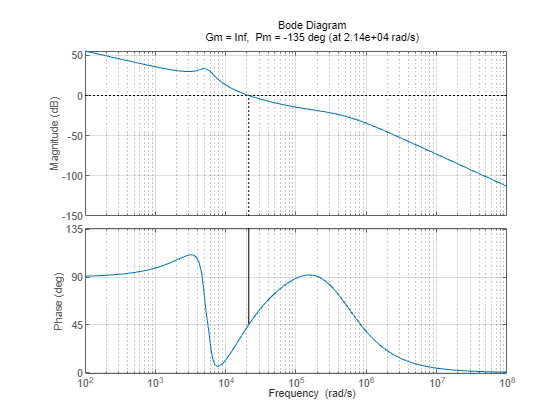


% Margin Bode Plot Displayed
figure()
margin(COMPLETECOMP*REALBUCKTF, options)
grid on